# Evitando obstáculos en Simulink

Ahora, se trata de evitar obstáculos en un escenario simulado, considerando que el dron está equipado con un Lidar. Se va a crear un nuevo escenario en el que se puedan establecer diferentes obstáculos que el dron debe evitar. 

Fuente: https://es.mathworks.com/help/uav/ug/uav-obstacle-avoidance-in-simulink.html

## Crear un escenario, un sensor Lidar y obstáculos

Crear un escenario y un punto de origen de este:

Scenario = uavScenario("UpdateRate",100,"ReferenceLocation",[0 0 0]);

Marcar la pose inicial del dron, que se señala con un cilindro rojo:

% addMesh(Scenario, shape, size, color)
addMesh(Scenario,"cylinder",{[1 1 1] [0 .001]},[1 0 0]);
InitialPosition = [1 1 -7];
InitialOrientation = [0 0 0];

Se crea la representación del dron, al que se puede poner un nombre (en este caso, yo le he puesto "UAV"), se establece en qué escenario se agrega el UAV, que es el que se ha creado anteriormente, y se agrega el sistema de referencia (en este caso, North-East-Down) y la pose inicial. La función `eul2quat` convierte los ángulos de Euler en cuaterniones, que son una forma común de representar la orientación en 3D.

platUAV = uavPlatform("UAV",Scenario, ...
                      "ReferenceFrame","NED", ...
                      "InitialPosition",InitialPosition, ...
                      "InitialOrientation",eul2quat(InitialOrientation));

Se actualiza la malla de representación y se agrega el dron, que se establece como cuadricóptero, un tipo de multirrotor con cuatro motores. La escala de la malla es 1.2. En el cuarto argumento se indica el color del UAV en la malla, para el que se ha escogido el azul (RGB).

El quinto argumento da la rotación de la malla completa, que en este caso son 180 grados alrededor del eje Z.

updateMesh(platUAV,"quadrotor",{1.2},[0 0 1],eul2tform([0 0 pi]));

Ahora, se especifica la resolución y rango del Lidar. 

El azimut es una medida angular utilizada para describir el ángulo en el plano horizontal con respecto a un punto de referencia., es decir, el ángulo entre una dirección de referencia y la dirección de interés, medido en el sentido de las agujas del reloj. `AzimuthResolution `indica el tamaño del paso angular utilizado para escanear en el plano horizontal. `ElevationResolution `define el tamaño del paso angular utilizado para escanear en el plano vertical. Esto se conoce como "escaneo en incremento", e implica recorrer sistemáticamente todas las posiciones dentro del rango definido, tomando en cuenta el tamaño del incremento especificado.

El parámetro `MaxRange `indica que el sensor puede detectar objetos o realizar mediciones de distancia hasta una distancia máxima de 7 unidades de longitud.

`AzimuthLimits` y `ElevationLimits` establecen el rango dentro del cual se realizará el escaneo en el escenario.

La elección de los valores de azimut y elevación ha sido arbitraria, pero en un escenario real se deben tener en cuenta una serie de factores como la cobertura requerida, las restricciones físicas, los requisitos de la planificación y la eficiencia del sistema utilizado.

AzimuthResolution = 0.5;      
ElevationResolution = 2;
MaxRange = 7;
AzimuthLimits = [-179 179];
ElevationLimits = [-15 15];

Se crea un generador de puntos en la nube Lidar, que son las mediciones tridimensionales capturadas por un Lidar de la UAV. 

`UpdateRate` define la tasa de actualización del Lidar, que en este caso se establece en 10 Hz, lo que significa que se generarán puntos a una frecuencia de 10 veces por segundo. También, se incluyen los rangos escogidos anteriormente. Además, se establece la opción `HasOrganizedOutput `en true, lo que indica que se generará una salida organizada de la nube de puntos lidar. Esto significa que los puntos estarán dispuestos en una matriz que representa el espacio escaneado y preserva su relación espacial. Esto facilita el procesamiento posterior de los datos lidar.

LidarModel = uavLidarPointCloudGenerator("UpdateRate",10, ...
                                         "MaxRange",MaxRange, ...
                                         "AzimuthResolution",AzimuthResolution, ...
                                         "ElevationResolution",ElevationResolution, ...
                                         "AzimuthLimits",AzimuthLimits, ...
                                         "ElevationLimits",ElevationLimits, ...                                       
                                         "HasOrganizedOutput",true);

Se equipa al dron el Lidar con las características definidas anteriormente. En este caso, se representa el dron en el punto (5, 0, 0) con respecto a la posición de la plataforma. Se inicia con una rotación de 180 grados respecto al eje.

uavSensor("Lidar",platUAV,LidarModel, ...
          "MountingLocation",[0 0 -0.4], ...
          "MountingAngles",[0 0 180]);

Se muestra el escenario completo al que se le han ido añadiendo las diferentes mallas:

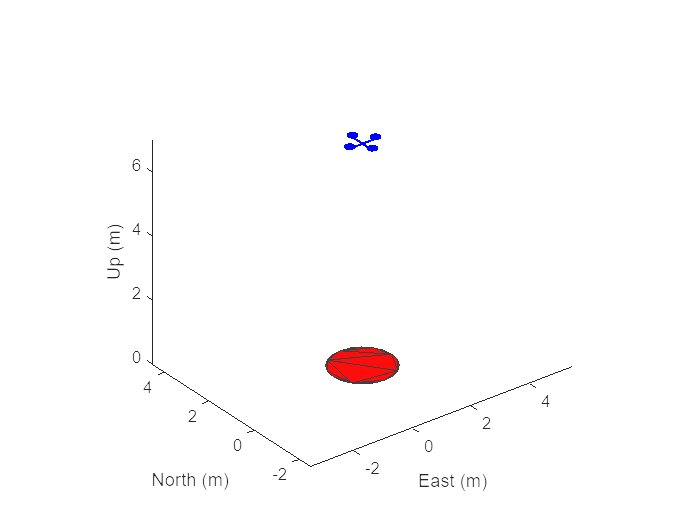

show3D(Scenario);

## Añadir obstáculos

Se ha elegido una forma cilíndrica para representar los árboles del bosque, es decir, los obstáculos. No es lo óptimo, pero al intentar cargar un fichero .slt con forma de árbol utilizando el parámetro `custom `en lugar de` cylinder `en` addmesh, `no se han tenido muy buenos resultados. 

Las referencias que se han utilizado aparecen aquí https://es.mathworks.com/help/uav/ref/uavscenario.addmesh.html#d124e66682

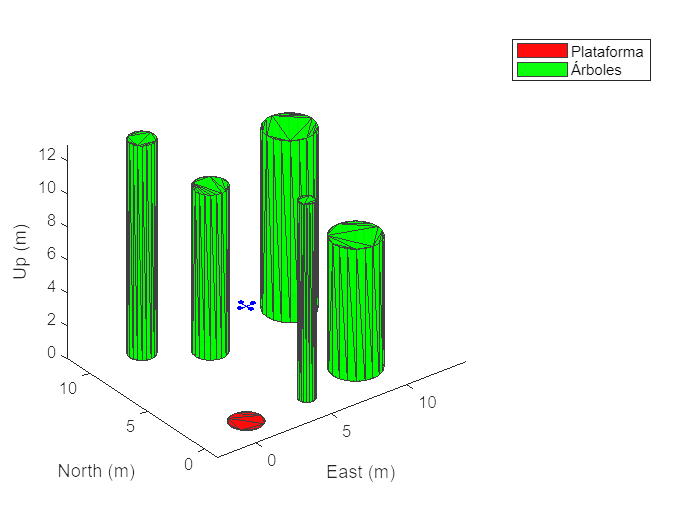

dimensiones = [1, 10, 0.8; 5, 1, 0.5; 4, 8, 1; 10, 9, 1.5; 9, 2, 1.5]; % Coordenadas (x, y, z) y radio de los cilindros
alturas = [13, 12, 10, 11, 8];  % Alturas de los cilindros

for i = 1:size(dimensiones, 1)
    centerX = dimensiones(i, 1);
    centerY = dimensiones(i, 2);
    radius = dimensiones(i, 3);
    zMin = 0;
    zMax = alturas(i);

    addMesh(Scenario, "cylinder", {[centerX, centerY, radius], [zMin, zMax]}, [0, 1, 0]);
end

show3D(Scenario);
legend("Plataforma", "Árboles");

## Puntos de interés

Se escogen los puntos que se ordena visitar al dron. Por simplicidad he establecido la misma altura (cuidado, es un sistema de referencia NED, lo que quiere decir que la última coordenada apunta a abajo, por lo que si quiero que esté por encima de la base, debe estar a altura -7). 

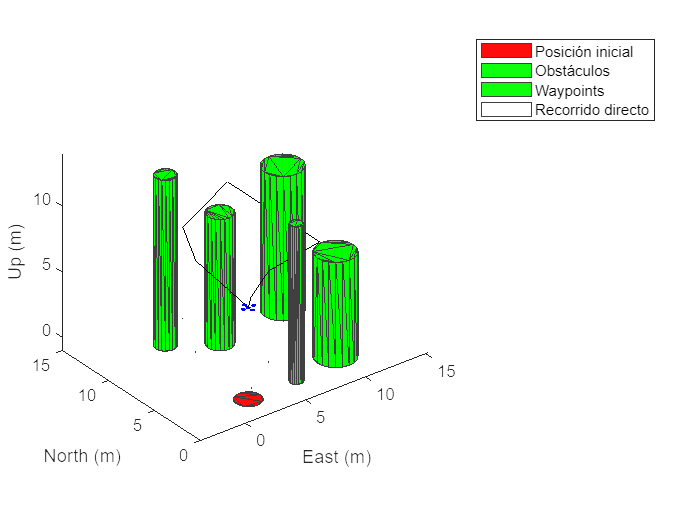

Waypoints = [InitialPosition; 2 2 -7; 4 5 -7; 5 10 -7; 15 10 -7; 12 4 -7; 8 2 -7; InitialPosition];

for i = 2:size(Waypoints, 1)
     addMesh(Scenario,"cylinder",{[Waypoints(i,2) Waypoints(i,1) 0.001] [0 0.1]},[1 1 1]);
end

show3D(Scenario);
hold on
plot3([InitialPosition(1, 2); Waypoints(:, 2)], [InitialPosition(1, 2); Waypoints(:, 1)], [-InitialPosition(1, 3); -Waypoints(:, 3)], 'k')
legend(["Posición inicial", "Obstáculos", "", "", "Waypoints", "", "", "Recorrido directo"])

Como se puede observar, realizar el recorrido en línea recta implicaría chocarse con los árboles, por lo que hay que suavizarlo.

### Componentes del UAV

Los siguientes parámetros representan los componentes de un sistema de control de un UAV, para generar comandos de control y actualizar el estado del UAV. El objetivo de este sistema es permitir el vuelo controlado del UAV y mantenerlo en una posición deseada, según las necesidades del vuelo y las condiciones del entorno.

El controlador de un UAV calcula las señales de control, la planta del cuadricóptero actualiza el estado del UAV y el subsistema de conversión realiza transformaciones de datos para la visualización.

Se menciona en la fuente que se han escogido por ensayo y error.

Los coeficientes de ganancia proporcional (Px, Py, Pz) determinan la contribución proporcional del error de posición al cálculo de las señales de control. Un valor mayor de ganancia proporcional puede ayudar a reducir el error de posición más rápidamente, pero también puede introducir oscilaciones o inestabilidades si se ajusta incorrectamente.

Los coeficientes de ganancia derivativa (Dx, Dy, Dz) representan la contribución derivativa al cálculo de las señales de control, que se basa en la tasa de cambio del error de posición y puede ayudar a reducir las oscilaciones y mejorar la estabilidad del UAV.

Los coeficientes de ganancia integral (Ix, Iy, Iz) representan la contribución integral al cálculo de las señales de control, que se utiliza para eliminar el error acumulado a lo largo del tiempo y garantizar que el UAV alcance la posición deseada de manera precisa. Sin embargo, en algunos casos, un valor alto de ganancia integral puede causar oscilaciones.

Los coeficientes de filtro (Nx, Ny, Nz) se utilizan para filtrar las señales de control y reducir el ruido. 

% Proportional Gains
Px = 6;
Py = 6;
Pz = 6.5;

% Derivative Gains
Dx = 1.5;
Dy = 1.5;
Dz = 2.5;

% Integral Gains
Ix = 0;
Iy = 0;
Iz = 0;

% Filter Coefficients
Nx = 10;
Ny = 10;
Nz = 14.4947065605712; 

% gravedad, masa del dron y tiempo de muestreo para los bloques del controlador y la planta
UAVSampleTime = 0.001;
Gravity = 9.81;
DroneMass = 0.1;

## Panel de control y modelo en Simulink 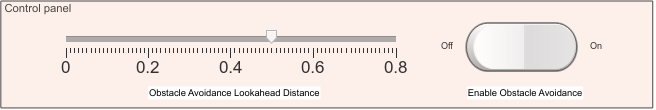

En primer lugar, se abre el modelo. Este se alimentará de los parámetros que se han ido especificando durante el script.

En otra ventana se abrirá el panel de control, en el que podemos modificar los parámetros, siempre manteniendo el nombre de los objetos de la malla. 

open_system("ObstacleAvoidanceDemo.slx");

## 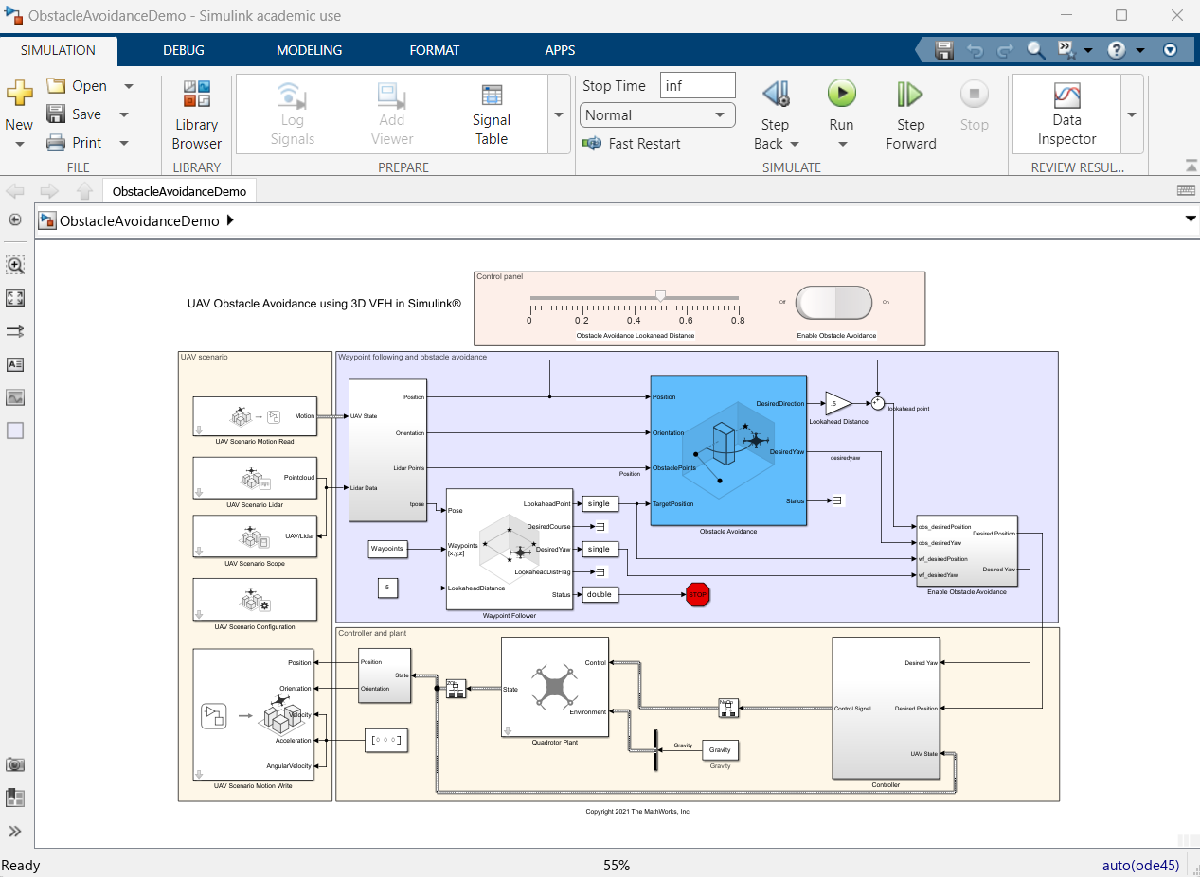

En la simulación (que se abre en otra ventana) se ejecuta el modelo, y se observa el movimiento del UAV. El UAV vuela a través de los waypoints evitando obstáculos, y luego la simulación se detiene. La franja que detecta el Lidar se marca sobre los objetos con colores naranjas y azules, y trata de evitar aproximarse a ella. 

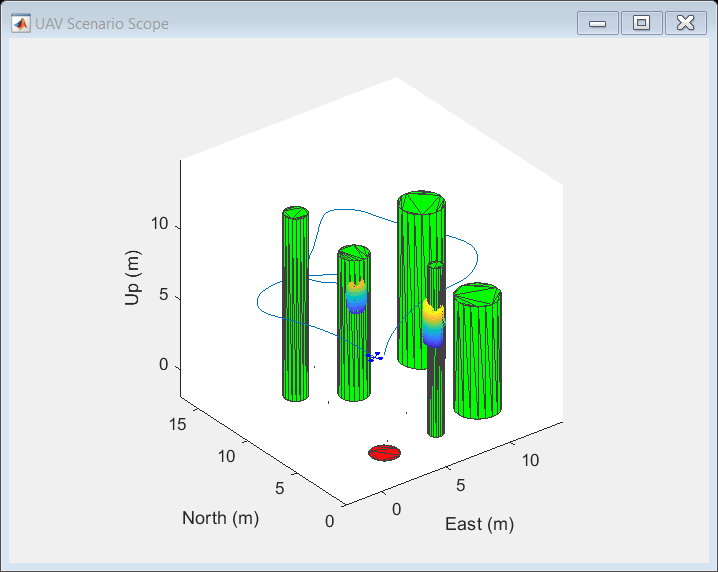

out = sim("ObstacleAvoidanceDemo.slx");